## Homework 2.5

clear all;
close all;
clc;

format short;

The equation $x^3-x^2-x+1=0$ has a double root at $\epsilon = 1$. Given $x^{(0)}=2$, does Newton method converge to $\epsilon$?

First of all, let's plot the function

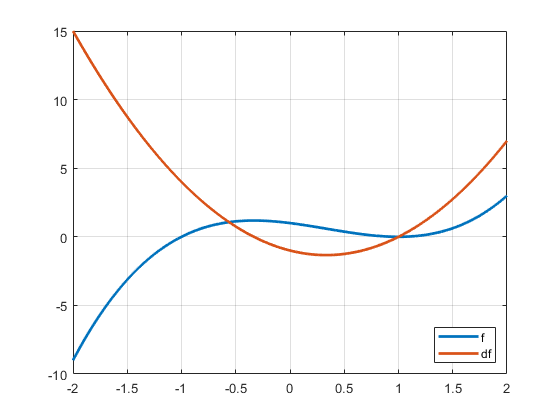

f = @(x) x.^3 - x.^2 - x + 1;
df = @(x) 3*x.^2 - 2*x - 1;

x = linspace(-2, 2, 1000);

figure();
plot(x, f(x), 'LineWidth', 2);
hold on;
plot(x, df(x), 'LineWidth', 2);
hold off;

grid on;
legend({'f', 'df'}, 'Location', 'southeast');

Let's apply the Newton method:

x0 = 2;
tol = 10e-15;
Nmax = 1e3;

[x, x_iter] = newton(f, df, x0, tol, Nmax);

fprintf('x: %g', x);

x: 1

display(x_iter);

x_iter =     2.0000    1.5714    1.3143    1.1671    1.0867    1.0442    1.0223    1.0112    1.0056    1.0028    1.0014    1.0007    1.0004    1.0002    1.0001    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



error = f(x_iter);

The method converges but, in order to achieve a quicker convergence, we can improve the Newton method formula:


$$x^{(k+1)} = x^{(k)} - m\frac{f(x^{(k)})}{f'(x^{(k)})}$$


So, let's try the improved Newton method

x0 = 2;
tol = 10e-15;
Nmax = 1e3;
m = 2;

[x, x_iter] = improved_newton(f, df, x0, tol, Nmax, m);

fprintf('x: %g', x);

x: 1

display(x_iter);

x_iter =     2.0000    1.1429    1.0046    1.0000    1.0000



error_improved = f(x_iter);

Let's compare the two errors:

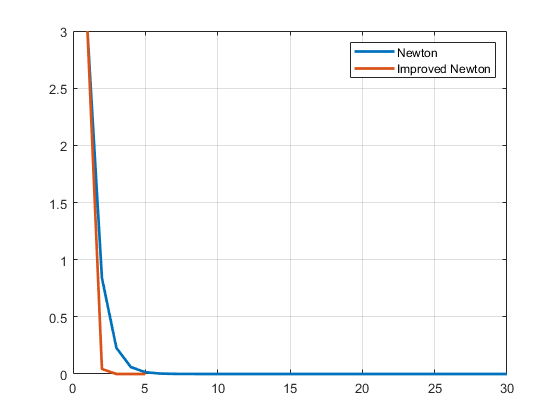

figure();
plot(error, 'LineWidth', 2);
hold on;
plot(error_improved, 'LineWidth', 2);
hold off;

grid on;
legend({'Newton', 'Improved Newton'}, 'Location', 'northeast');

**With the improved Newton method we reach the exact solution in 5 iterations instead of 30 iterations, so an order of magnitude better.**

### Functions

function [x, x_iter] = newton(f, df, x0, tol, Nmax)
    % Nmax since we don't know a priori if with the passed
    % tol we will reach a convergence

    x_iter(1) = x0;
    
    for k = 2:Nmax
        
        % Check if the derivative is zero or simil-zero
        if abs(df(x_iter(k-1))) < 1e-8
            break;
        end
        
        x_iter(k) = x_iter(k-1) - (f(x_iter(k-1)) / df(x_iter(k-1)));
    
        if abs(x_iter(k) - x_iter(k-1)) < tol
            break;
        end
    end
    
    x = x_iter(end);
end

Improved Newton method

function [x, x_iter] = improved_newton(f, df, x0, tol, Nmax, m)
    % Nmax since we don't know a priori if with the passed
    % tol we will reach a convergence

    x_iter(1) = x0;
    
    for k = 2:Nmax
        
        % Check if the derivative is zero or simil-zero
        if abs(df(x_iter(k-1))) < 1e-8
            break;
        end
        
        x_iter(k) = x_iter(k-1) - m*(f(x_iter(k-1)) / df(x_iter(k-1)));
    
        if abs(x_iter(k) - x_iter(k-1)) < tol
            break;
        end
    end
    
    x = x_iter(end);
end